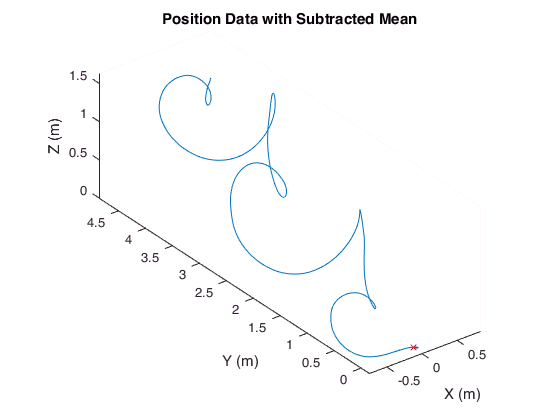

% Load data
load 'figure8-3d-big.mat';
Fs = 100;
accels = [Acceleration.X Acceleration.Y Acceleration.Z];
orients = [Orientation.X Orientation.Y Orientation.Z];
dts = diff([seconds(Acceleration.Timestamp - Acceleration.Timestamp(1))]);

% Transform coordinate system from phone frame to global frame
for i=1:length(accels)
    accels(i,:) = [inv(Rotation(orients(i,1), orients(i,2), orients(i,3)))*accels(i,:)']';
end

start = 500;
accels_final = accels(start:end,:); % Pick the range we want to plot
%accels_final = accels_final - mean(accels(219:497,:));
accels_final = accels_final - mean(accels_final); % Substract the mean to center the data and eliminate gravity
dts = dts(start:end);

% Double integration to get positions
v = [0 0 0];
for i=2:length(accels_final)
    v(i,:) = v(i-1,:) + accels_final(i-1,:)*dts(i-1);
end

pos = [0 0 0];
for i=2:length(accels_final)
    pos(i,:) = pos(i-1,:) + v(i-1,:)*dts(i-1);
end

% Plot
figure; hold on 
plot3(pos(:,1),pos(:,2),pos(:,3));
view(3); xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)'); axis equal
plot3(0,0,0,'rx')
title('Position Data with Subtracted Mean');
hold off

% Frequency Plot Testing
o=200

o = 200

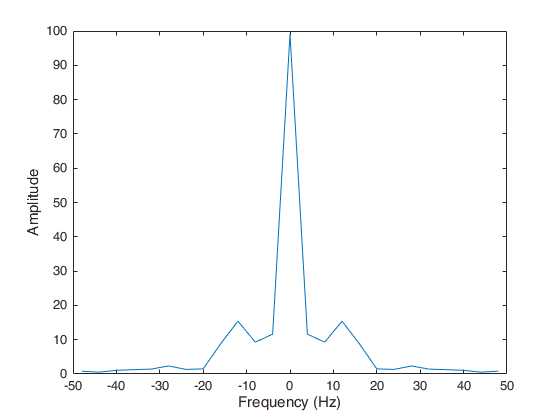

mag = sqrt(accels_final(:,1).^2 + accels_final(:,2).^2 + accels_final(:,3).^2);
make_freq_plot(mag(1+o:25+o), 100)

freq = remove_zeros(mag(1+o:25+o), 100)

freq = 12

function freq = remove_zeros(x, Fs)
    N = length(x);
    X_shifted = abs(fftshift(fft(x)));
    freqs_shifted_hz = (linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2))*Fs/(2*pi);
    sorted = sort(X_shifted);
    keep = sorted(end-1);
    r1 = find(X_shifted == keep);
    freq = abs(freqs_shifted_hz(r1));
    freq = freq(1);
end

function make_freq_plot(x, Fs)
    N = length(x);
    X_shifted = fftshift(fft(x));
    freqs_shifted_hz = (linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2))*Fs/(2*pi);
    plot(freqs_shifted_hz, abs(X_shifted));
    xlabel('Frequency (Hz)'); ylabel('Amplitude');
end

% Define rotation matrices (for MATLAB)
function r=Rotation(yaw, pitch, roll)
    r = Rx(roll)*Ry(pitch)*Rz(yaw);
end

function r=Rx(theta)
    r = [cosd(theta) 0 -sind(theta); 0 1 0; sind(theta) 0 cosd(theta)];
end

function r=Ry(theta)
    r = [1 0 0; 0 cosd(theta) -sind(theta); 0 sind(theta) cosd(theta)];
end

function r=Rz(theta)
    r = [cosd(theta) -sind(theta) 0; sind(theta) cosd(theta) 0; 0 0 1];
end

function y=notch_filter(x, Fs, omega_o)
    q = 0.99;
    omega_o = omega_o*2*pi/Fs; 
    A = 2*q*cos(omega_o);
    B = -q^2;
    P = 1;
    Q = -2*cos(omega_o);
    R = 1;
    y = zeros(length(x)+2,1);
    x = [x; 0; 0]; 
    for k=3:length(y)
        y(k) = A*y(k-1) + B*y(k-2) + P*x(k) + Q*x(k-1) + R*x(k-2);
    end
end

function y=filter_range(x, Fs, F_low, F_high, intensity)
    N = length(x);
    X_shifted = fftshift(fft(x));
    freqs_shifted_hz = (linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2))*Fs/(2*pi);
    freqs_to_filter = freqs_shifted_hz > F_low ...
                  & freqs_shifted_hz < F_high;
    X_shifted(freqs_to_filter) = X_shifted(freqs_to_filter)/intensity;
    freqs_to_filter = freqs_shifted_hz <- F_low ...
                  & freqs_shifted_hz >- F_high;
    X_shifted(freqs_to_filter) = X_shifted(freqs_to_filter)/intensity;
    y = ifft(ifftshift(X_shifted));
end